# This is the live script for ESE 6190 HW4 MPC Theory I problem 1-11

clear all
clc
%% Basic Deifinition, run this block first
% Define system matrixcs:
A = [0.7115, -0.4345; 0.4345, 0.8853];
% Define input matrixcs:
B = [0.2173;0.0573];
% sampling time
Ts = 0.1;
% Horizon Length
N = 5;
% Define weight matrices:
Q = eye(2);
R = 1;
% Define initial state:
x0 = [0;10];

## Ex 1.5 Calculate the terminal cost

% set terminal weight as solution for discrete Lyapunov equation
P_L = dlyap(A,Q)

P_L =     5.5319   -0.9995
   -0.9995    5.8982


Norm_PL = norm(P_L)

Norm_PL = 6.7312

% set terminal weight as solution for LQR problem
[~,P_R,~] = dlqr(A,B,Q,R,0)

P_R =     3.8097    0.9640
    0.9640    4.5173


Norm_PR = norm(P_R)

Norm_PR = 5.1904

## Ex 1.6 Simple MPC simulation and tuning

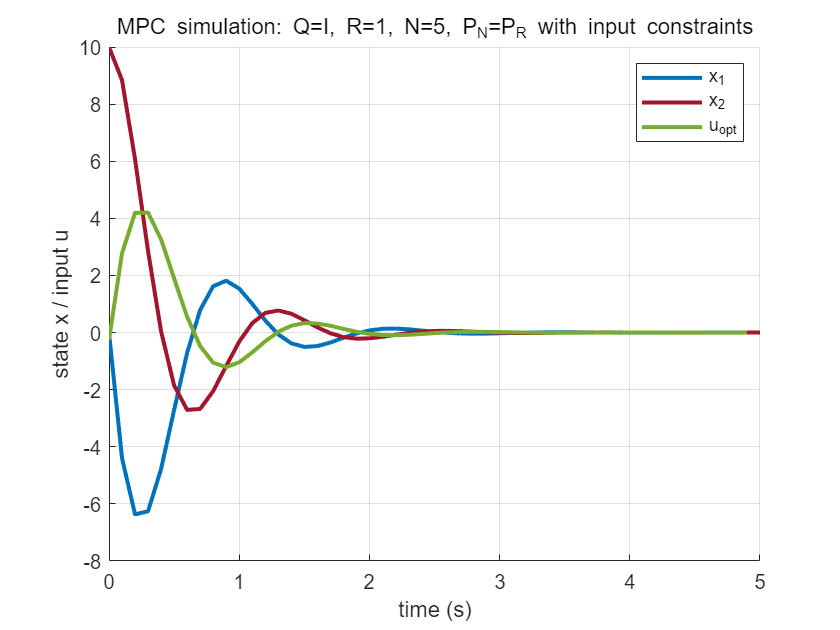

% simulation time:
T_sim = 5;
% Terminal weight matrix: choose LQR solution
[~,P_N,~] = dlqr(A,B,Q,R,0);
n = size(A, 1);
m = size(B, 2);
umin = -5*ones(m,1);
umax = 5*ones(m,1);
xmin = -inf*ones(n,1);
xmax = inf*ones(n,1);
U = zeros((T_sim/Ts)*m,1);
X = zeros((T_sim/Ts)*n,1);

for i = 1 : (T_sim/Ts)
    if i == 1
        x = x0;
    end
    u = mympc(A,B,Q,R,P_N,N,umin,umax,xmin,xmax,x);
    if isnan(u)
        disp(['At step ',num2str(i),' no control input found, problem infeasible'])
        break
    end
    xp = system_sim(x,u,A,B);
    U((i-1)*m+1:i*m,1) = u;
    X((i-1)*n+1:i*n,1) = xp;
    x = xp;
end
X = [x0;X];

% plot the result
figure
hold on
grid on
plot(0:Ts:T_sim,X(1:n:end),'-','LineWidth',2,'Color','#0072BD')
plot(0:Ts:T_sim,X(2:n:end),'-','LineWidth',2,'Color','#A2142F')
plot(0:Ts:T_sim-Ts,U(1:m:end),'-','LineWidth',2,'Color','#77AC30')
legend('x_1','x_2','u_{opt}')
title('MPC simulation: Q=I, R=1, N=5, P_N=P_R with input constraints')
ylabel('state x / input u')
xlabel('time (s)')

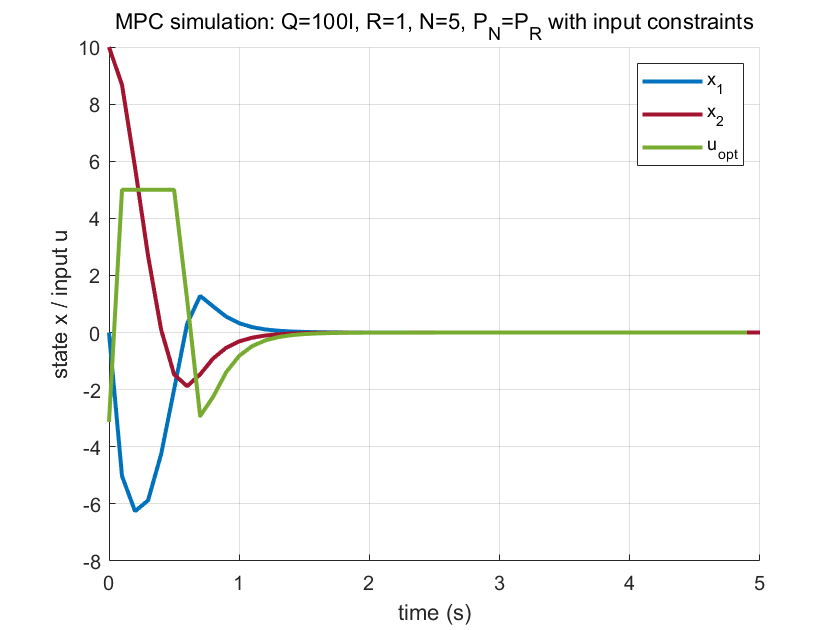


%% tune the MPC controller to reduce overshoot and oscillation
U = zeros((T_sim/Ts)*m,1);
X = zeros((T_sim/Ts)*n,1);

for i = 1 : (T_sim/Ts)
    if i == 1
        x = x0;
    end
    u = mympc(A,B,100*Q,R,P_N,N,umin,umax,xmin,xmax,x);
    if isnan(u)
        disp(['At step ',num2str(i),' no control input found, problem infeasible'])
        break
    end
    xp = system_sim(x,u,A,B);
    U((i-1)*m+1:i*m,1) = u;
    X((i-1)*n+1:i*n,1) = xp;
    x = xp;
end
X = [x0;X];

% plot the states and inputs for this system
figure
hold on
grid on
plot(0:Ts:T_sim,X(1:n:end),'-','LineWidth',2,'Color','#0072BD')
plot(0:Ts:T_sim,X(2:n:end),'-','LineWidth',2,'Color','#A2142F')
plot(0:Ts:T_sim-Ts,U(1:m:end),'-','LineWidth',2,'Color','#77AC30')
legend('x_1','x_2','u_{opt}')
title('MPC simulation: Q=100I, R=1, N=5, P_N=P_R with input constraints')
ylabel('state x / input u')
xlabel('time (s)')

## MPT Toolbox verification for Ex 1.6

% %% we can also check the result using the MPT toolbox
% % follow the instructions given by MPT toolbox
% % uncomment this block if needed
% prediction_model = LTISystem('A', [0.7115, -0.4345; 0.4345, 0.8853], 'B', [0.2173;0.0573],'Ts', Ts);
% prediction_model.x.min = [-inf; -inf];
% prediction_model.x.max = [inf; inf];
% prediction_model.u.min = -5;
% prediction_model.u.max = 5;
% prediction_model.x.penalty = QuadFunction([1 0; 0 1]);
% prediction_model.u.penalty = QuadFunction(1);
% prediction_model.x.with('terminalPenalty');
% PN = prediction_model.LQRPenalty;
% prediction_model.x.terminalPenalty = PN;
% N = 5;
% mpc = MPCController(prediction_model, N);
% simulation_model = LTISystem('A', [0.7115, -0.4345; 0.4345, 0.8853], 'B', [0.2173;0.0573],'Ts', Ts);
% loop = ClosedLoop(mpc, simulation_model);
% Nsim = 50;
% data = loop.simulate(x0, Nsim);
% figure
% hold on
% grid on
% plot(0:Ts:T_sim,data.X(1,:),'-','LineWidth',2,'Color','#0072BD')
% plot(0:Ts:T_sim,data.X(2,:),'-','LineWidth',2,'Color','#A2142F')
% plot(0:Ts:T_sim-Ts,data.U,'-','LineWidth',2,'Color','#77AC30')
% legend('x_1','x_2','u_{opt}')
% title('MPC with input constraints: Verification using MPT toolbox')
% ylabel('state x / input u')
% xlabel('time (s)')
% diff_X1 = data.X(1,:)'-X(1:n:end);
% diff_X2 = data.X(2,:)'-X(2:n:end);
% diff_U = data.U'-U;
% flag = (all(abs(diff_X1)<1e-8)) & (all(abs(diff_X2)<1e-8)) & (all(abs(diff_U)<1e-8))

## Ex 1.7, short-horizon MPC with improper terminal cost

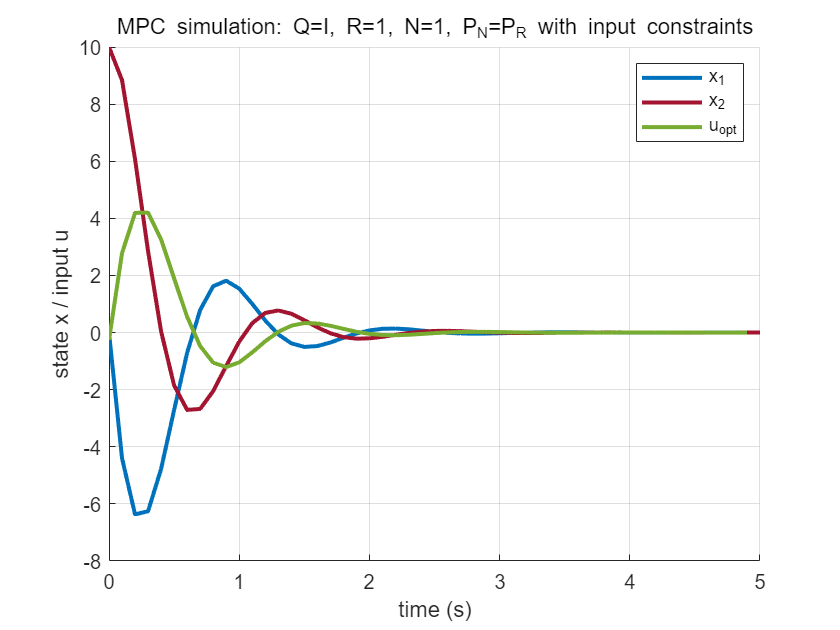

% simulation time:
T_sim = 5;
% change the horizon
N = 1;
% Terminal weight matrix: choose LQR solution
[~,P_N,~] = dlqr(A,B,Q,R,0);
n = size(A, 1);
m = size(B, 2);
umin = -5*ones(m,1);
umax = 5*ones(m,1);
xmin = -inf*ones(n,1);
xmax = inf*ones(n,1);
U = zeros((T_sim/Ts)*m,1);
X = zeros((T_sim/Ts)*n,1);

for i = 1 : (T_sim/Ts)
    if i == 1
        x = x0;
    end
    u = mympc(A,B,Q,R,P_N,N,umin,umax,xmin,xmax,x);
    if isnan(u)
        disp(['At step ',num2str(i),' no control input found, problem infeasible'])
        break
    end
    xp = system_sim(x,u,A,B);
    U((i-1)*m+1:i*m,1) = u;
    X((i-1)*n+1:i*n,1) = xp;
    x = xp;
end
X = [x0;X];

% plot the states and inputs for this system: no signifincant difference
figure
hold on
grid on
plot(0:Ts:T_sim,X(1:n:end),'-','LineWidth',2,'Color','#0072BD')
plot(0:Ts:T_sim,X(2:n:end),'-','LineWidth',2,'Color','#A2142F')
plot(0:Ts:T_sim-Ts,U(1:m:end),'-','LineWidth',2,'Color','#77AC30')
legend('x_1','x_2','u_{opt}')
title('MPC simulation: Q=I, R=1, N=1, P_N=P_R with input constraints')
ylabel('state x / input u')
xlabel('time (s)')

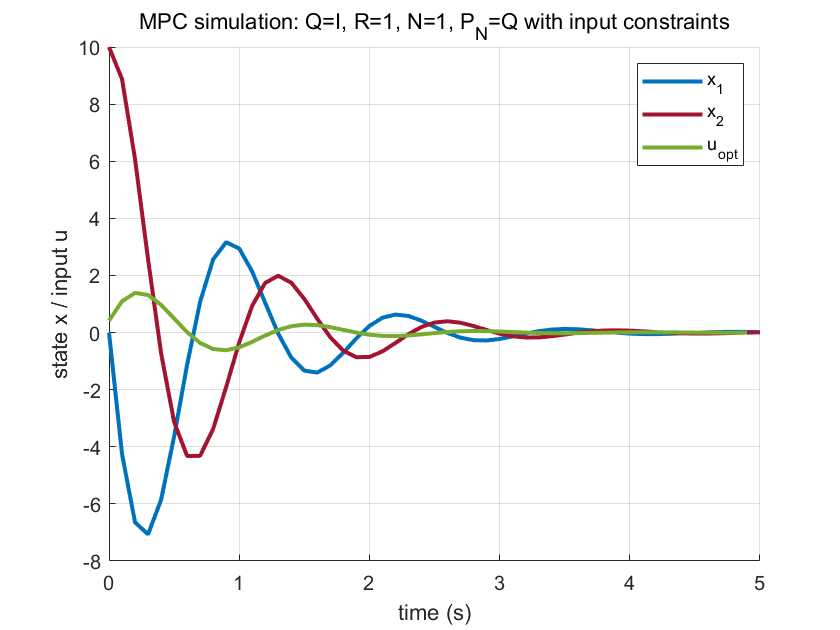


% Terminal weight matrix: choose Q solution
U = zeros((T_sim/Ts)*m,1);
X = zeros((T_sim/Ts)*n,1);
for i = 1 : (T_sim/Ts)
    if i == 1
        x = x0;
    end
    u = mympc(A,B,Q,R,Q,N,umin,umax,xmin,xmax,x);
    if isnan(u)
        disp(['At step ',num2str(i),' no control input found, problem infeasible'])
        break
    end
    xp = system_sim(x,u,A,B);
    U((i-1)*m+1:i*m,1) = u;
    X((i-1)*n+1:i*n,1) = xp;
    x = xp;
end
X = [x0;X];

% plot the states and inputs for this system: tend to be unstable
figure
hold on
grid on
plot(0:Ts:T_sim,X(1:n:end),'-','LineWidth',2,'Color','#0072BD')
plot(0:Ts:T_sim,X(2:n:end),'-','LineWidth',2,'Color','#A2142F')
plot(0:Ts:T_sim-Ts,U(1:m:end),'-','LineWidth',2,'Color','#77AC30')
legend('x_1','x_2','u_{opt}')
title('MPC simulation: Q=I, R=1, N=1, P_N=Q with input constraints')
ylabel('state x / input u')
xlabel('time (s)')

## MPT Toolbox verification for Ex 1.7

% % check situation for terminal cost being Q=eye(2)
% % uncomment this block if needed
% prediction_model = LTISystem('A', [0.7115, -0.4345; 0.4345, 0.8853], 'B', [0.2173;0.0573],'Ts', Ts);
% prediction_model.x.min = [-inf; -inf];
% prediction_model.x.max = [inf; inf];
% prediction_model.u.min = -5;
% prediction_model.u.max = 5;
% prediction_model.x.penalty = QuadFunction([1 0; 0 1]);
% prediction_model.u.penalty = QuadFunction(1);
% prediction_model.x.with('terminalPenalty');
% PN = QuadFunction([1 0; 0 1]);
% prediction_model.x.terminalPenalty = PN;
% N = 1;
% mpc = MPCController(prediction_model, N);
% simulation_model = LTISystem('A', [0.7115, -0.4345; 0.4345, 0.8853], 'B', [0.2173;0.0573],'Ts', Ts);
% loop = ClosedLoop(mpc, simulation_model);
% Nsim = 50;
% data = loop.simulate(x0, Nsim);
% figure
% hold on
% grid on
% plot(0:Ts:T_sim,data.X(1,:),'-','LineWidth',2,'Color','#0072BD')
% plot(0:Ts:T_sim,data.X(2,:),'-','LineWidth',2,'Color','#A2142F')
% plot(0:Ts:T_sim-Ts,data.U,'-','LineWidth',2,'Color','#77AC30')
% legend('x_1','x_2','u_{opt}')
% title('MPC without any constraints: Verification using MPT toolbox')
% ylabel('state x / input u')
% xlabel('time (s)')
% diff_X1 = data.X(1,:)'-X(1:n:end);
% diff_X2 = data.X(2,:)'-X(2:n:end);
% diff_U = data.U'-U;
% flag = (all(abs(diff_X1)<1e-8)) & (all(abs(diff_X2)<1e-8)) & (all(abs(diff_U)<1e-8))

## Ex 1.8, compare LQR controller with MPC controller

% Horizon Length
N = 2;
% Define weight matrices:
Q = 100*eye(2);
R = 1;
% Define initial state:
x0 = [0;10];
% set terminal weight as solution for LQR problem or Lyapunov equation and solve mpc
[K_R,P_R,~] = dlqr(A,B,Q,R,0)

K_R =     3.6944    1.3297


P_R =   127.4664   54.8601
   54.8601  301.8910


P_L = dlyap(A,Q)

P_L =   553.1943  -99.9496
  -99.9496  589.8151


n = size(A, 1);
m = size(B, 2);
umin = -5*ones(m,1);
umax = 5*ones(m,1);
xmin = -inf*ones(n,1);
xmax = inf*ones(n,1);

u_R = mympc(A,B,Q,R,P_R,N,umin,umax,xmin,xmax,x0);
u_L = mympc(A,B,Q,R,P_L,N,umin,umax,xmin,xmax,x0);
% compare mpc control input (terminal LQR and terminal Lyapunov) and lqr control input
u_mpc_R = u_R

u_mpc_R = -5

u_mpc_L = u_L

u_mpc_L = -3.0946

u_lqr = -K_R*x0

u_lqr = -13.2966

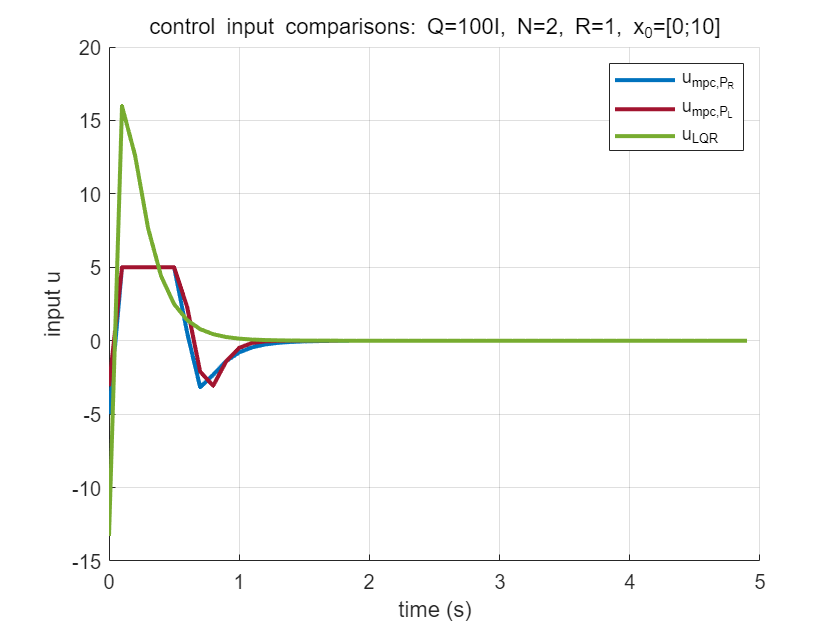


% compare the time history of the three cases
U_R = zeros((T_sim/Ts)*m,1);
U_L = zeros((T_sim/Ts)*m,1);
U_lqr = zeros((T_sim/Ts)*m,1);
for i = 1 : (T_sim/Ts)
    if i == 1
        x_R = x0;
        x_L = x0;
        x_lqr = x0;
    end
    u_R = mympc(A,B,Q,R,P_R,N,umin,umax,xmin,xmax,x_R);
    u_L = mympc(A,B,Q,R,P_L,N,umin,umax,xmin,xmax,x_L);
    u_lqr = -K_R*x_lqr;

    xp_R = system_sim(x_R,u_R,A,B);
    xp_L = system_sim(x_L,u_L,A,B);
    xp_lqr = system_sim(x_lqr,u_lqr,A,B);
    U_R((i-1)*m+1:i*m,1) = u_R;
    U_L((i-1)*m+1:i*m,1) = u_L;
    U_lqr((i-1)*m+1:i*m,1) = u_lqr;

    x_R = xp_R;
    x_L = xp_L;
    x_lqr = xp_lqr;
end
figure
hold on
grid on
plot(0:Ts:T_sim-Ts,U_R,'-','LineWidth',2,'Color','#0072BD')
plot(0:Ts:T_sim-Ts,U_L,'-','LineWidth',2,'Color','#A2142F')
plot(0:Ts:T_sim-Ts,U_lqr,'-','LineWidth',2,'Color','#77AC30')
legend('u_{mpc,P_R}','u_{mpc,P_L}','u_{LQR}')
title('control input comparisons: Q=100I, N=2, R=1, x_0=[0;10]')
ylabel('input u')
xlabel('time (s)')



%% change the state to [0.1;0.1] and do the same thing
x0 = [0.1;0.1];
u_R = mympc(A,B,Q,R,P_R,N,umin,umax,xmin,xmax,x0);
u_L = mympc(A,B,Q,R,P_L,N,umin,umax,xmin,xmax,x0);
u_mpc_R = u_R

u_mpc_R = -0.5024

u_mpc_L = u_L

u_mpc_L = -0.7538

u_lqr = -K_R*x0

u_lqr = -0.5024

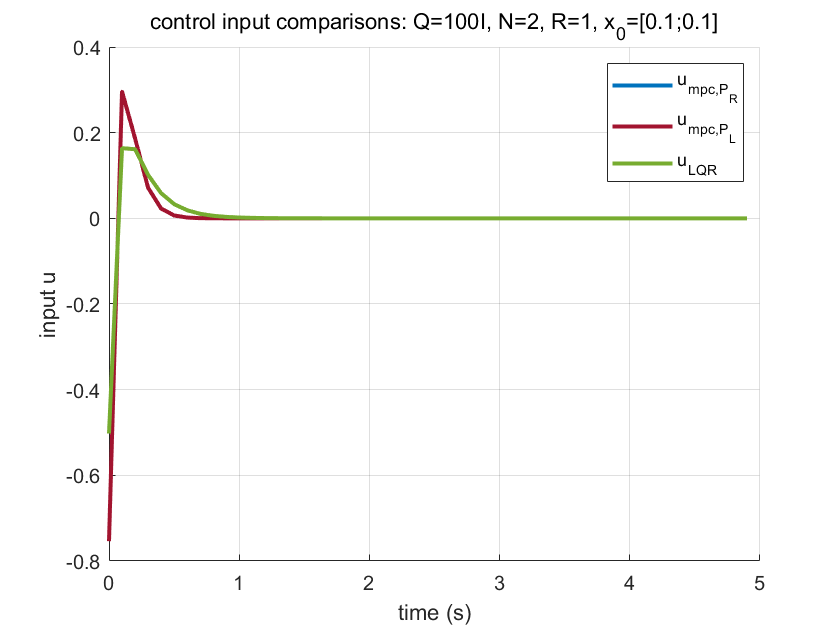


% compare the time history of the three cases
U_R = zeros((T_sim/Ts)*m,1);
U_L = zeros((T_sim/Ts)*m,1);
U_lqr = zeros((T_sim/Ts)*m,1);
for i = 1 : (T_sim/Ts)
    if i == 1
        x_R = x0;
        x_L = x0;
        x_lqr = x0;
    end
    u_R = mympc(A,B,Q,R,P_R,N,umin,umax,xmin,xmax,x_R);
    u_L = mympc(A,B,Q,R,P_L,N,umin,umax,xmin,xmax,x_L);
    u_lqr = -K_R*x_lqr;

    xp_R = system_sim(x_R,u_R,A,B);
    xp_L = system_sim(x_L,u_L,A,B);
    xp_lqr = system_sim(x_lqr,u_lqr,A,B);
    U_R((i-1)*m+1:i*m,1) = u_R;
    U_L((i-1)*m+1:i*m,1) = u_L;
    U_lqr((i-1)*m+1:i*m,1) = u_lqr;

    x_R = xp_R;
    x_L = xp_L;
    x_lqr = xp_lqr;
end
figure
hold on
grid on
plot(0:Ts:T_sim-Ts,U_R,'-','LineWidth',2,'Color','#0072BD')
plot(0:Ts:T_sim-Ts,U_L,'-','LineWidth',2,'Color','#A2142F')
plot(0:Ts:T_sim-Ts,U_lqr,'-','LineWidth',2,'Color','#77AC30')
legend('u_{mpc,P_R}','u_{mpc,P_L}','u_{LQR}')
title('control input comparisons: Q=100I, N=2, R=1, x_0=[0.1;0.1]')
ylabel('input u')
xlabel('time (s)')

## MPT Toolbox verification for Ex 1.8

% % uncomment this block if needed
% % system basics
% prediction_model = LTISystem('A', [0.7115, -0.4345; 0.4345, 0.8853], 'B', [0.2173;0.0573],'Ts', Ts);
% prediction_model.x.min = [-inf; -inf];
% prediction_model.x.max = [inf; inf];
% prediction_model.u.min = -5;
% prediction_model.u.max = 5;
% prediction_model.x.penalty = QuadFunction([100 0; 0 100]);
% prediction_model.u.penalty = QuadFunction(1);
% prediction_model.x.with('terminalPenalty');
% simulation_model = LTISystem('A', [0.7115, -0.4345; 0.4345, 0.8853], 'B', [0.2173;0.0573],'Ts', Ts);
% N = 2;
% x0 = [0;10];
% % with lqr penalty
% PN = prediction_model.LQRPenalty;
% prediction_model.x.terminalPenalty = PN;
% mpc = MPCController(prediction_model, N);
% loop = ClosedLoop(mpc, simulation_model);
% Nsim = 50;
% data = loop.simulate(x0, Nsim);
% u_mpc_R_ver = data.U(1)
% % with lyapunov penalty
% PN = QuadFunction(P_L);
% prediction_model.x.terminalPenalty = PN;
% mpc = MPCController(prediction_model, N);
% loop = ClosedLoop(mpc, simulation_model);
% Nsim = 50;
% data = loop.simulate(x0, Nsim);
% u_mpc_L_ver = data.U(1)
% 
% %% change the initial state and see the result
% x0 = [0.1;0.1];
% % with lqr penalty
% PN = prediction_model.LQRPenalty;
% prediction_model.x.terminalPenalty = PN;
% mpc = MPCController(prediction_model, N);
% loop = ClosedLoop(mpc, simulation_model);
% Nsim = 50;
% data = loop.simulate(x0, Nsim);
% u_mpc_R_ver = data.U(1)
% % with lyapunov penalty
% PN = QuadFunction(P_L);
% prediction_model.x.terminalPenalty = PN;
% mpc = MPCController(prediction_model, N);
% loop = ClosedLoop(mpc, simulation_model);
% Nsim = 50;
% data = loop.simulate(x0, Nsim);
% u_mpc_L_ver = data.U(1)

## Ex 1.10 implement the state constraints on x2 to restrict undershoot

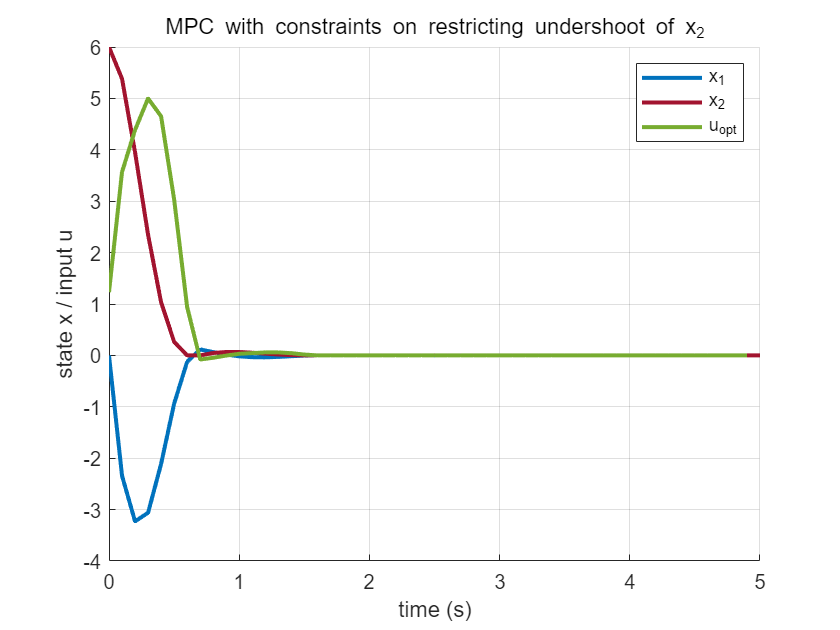

% use parameters for Ex 1.6
N = 5;
Q = eye(2);
R = 1;
T_sim = 5;
[~,P_N,~] = dlqr(A,B,Q,R,0);
n = size(A, 1);
m = size(B, 2);
% state and input constraints: x2 should not have undershoot
umin = -5*ones(m,1);
umax = 5*ones(m,1);
xmin = [-inf;0];
xmax = inf*ones(n,1);

% initial condition
x0 = [0;6];

% record and plot
U = zeros((T_sim/Ts)*m,1);
X = zeros((T_sim/Ts)*n,1);

for i = 1 : (T_sim/Ts)
    if i == 1
        x = x0;
    end
    u = mympc(A,B,Q,R,P_N,N,umin,umax,xmin,xmax,x);
    if isnan(u)
        disp(['At step ',num2str(i),' no control input found, problem infeasible'])
        break
    end
    xp = system_sim(x,u,A,B);
    U((i-1)*m+1:i*m,1) = u;
    X((i-1)*n+1:i*n,1) = xp;
    x = xp;
end
X = [x0;X];

% plot the states and inputs for this system
figure
hold on
grid on
plot(0:Ts:T_sim,X(1:n:end),'-','LineWidth',2,'Color','#0072BD')
plot(0:Ts:T_sim,X(2:n:end),'-','LineWidth',2,'Color','#A2142F')
plot(0:Ts:T_sim-Ts,U(1:m:end),'-','LineWidth',2,'Color','#77AC30')
legend('x_1','x_2','u_{opt}')
title('MPC with constraints on restricting undershoot of x_2')
ylabel('state x / input u')
xlabel('time (s)')

## MPT Toolbox verification for Ex 1.10

% % uncomment this block if needed
% % system basics
% prediction_model = LTISystem('A', [0.7115, -0.4345; 0.4345, 0.8853], 'B', [0.2173;0.0573],'Ts', Ts);
% prediction_model.x.min = [-1e13; 0];
% prediction_model.x.max = [inf; inf];
% prediction_model.u.min = -5;
% prediction_model.u.max = 5;
% prediction_model.x.penalty = QuadFunction([1 0; 0 1]);
% prediction_model.u.penalty = QuadFunction(1);
% prediction_model.x.with('terminalPenalty');
% simulation_model = LTISystem('A', [0.7115, -0.4345; 0.4345, 0.8853], 'B', [0.2173;0.0573],'Ts', Ts);
% PN = prediction_model.LQRPenalty;
% prediction_model.x.terminalPenalty = PN;
% N = 5;
% x0 = [0;6];
% mpc = MPCController(prediction_model, N);
% loop = ClosedLoop(mpc, simulation_model);
% Nsim = 50;
% data = loop.simulate(x0, Nsim);
% figure
% hold on
% grid on
% plot(0:Ts:T_sim,data.X(1,:),'-','LineWidth',2,'Color','#0072BD')
% plot(0:Ts:T_sim,data.X(2,:),'-','LineWidth',2,'Color','#A2142F')
% plot(0:Ts:T_sim-Ts,data.U,'-','LineWidth',2,'Color','#77AC30')
% legend('x_1','x_2','u_{opt}')
% title('MPC without any constraints: Verification using MPT toolbox')
% ylabel('state x / input u')
% xlabel('time (s)')
% diff_X1 = data.X(1,:)'-X(1:n:end);
% diff_X2 = data.X(2,:)'-X(2:n:end);
% diff_U = data.U'-U;
% flag = (all(abs(diff_X1)<1e-4)) & (all(abs(diff_X2)<1e-4)) & (all(abs(diff_U)<1e-4))

% % initial condition change, no solution
% x0 = [0;10];
% 
% % record and plot
% U = zeros((T_sim/Ts)*m,1);
% X = zeros((T_sim/Ts)*n,1);
% 
% for i = 1 : (T_sim/Ts)
%     if i == 1
%         x = x0;
%     end
%     u = mympc(A,B,Q,R,P_N,N,umin,umax,xmin,xmax,x);
%     if isnan(u)
%         disp(['At step ',num2str(i),' no control input found, problem infeasible'])
%         break
%     end
%     xp = system_sim(x,u,A,B);
%     U((i-1)*m+1:i*m,1) = u;
%     X((i-1)*n+1:i*n,1) = xp;
%     x = xp;
% end
% %% MPT Toolbox verification for Ex 1.10.2
% x0 = [0;10];
% mpc = MPCController(prediction_model, N);
% loop = ClosedLoop(mpc, simulation_model);
% Nsim = 50;
% data = loop.simulate(x0, Nsim);

function u = mympc(A,B,Q,R,P,N,umin,umax,xmin,xmax,x)
%% This is the function used to solve the linear mpc problem
    %% linear quadratic optimal control via recursive approach
    %% The method is batch-approach based with substitution, i.e. shooting
    %% essentially, it is solving multiparametric QP about initial state x
    %% input:
    %  A: system matrix; B: Input matrix; N: control horizon;
    %  Q,R: weight matrices for states and inputs, respectively;
    %  P: terminal cost weight matrix;
    %  umin,umax: box constraints for control inputs, vectors
    %  xmin,xmax: box constraints for state inputs, vectors
    %  x: the current state (or say, the initial state for every mpc planning)
    %% output:
    %  u: the mpc control sequence u = [u0; u1; ...; uN-1];

    % first, rollout the dynamics to get Sx(mathcalA) and Su(mathcalB):
    n = size(A, 1);
    m = size(B, 2);
    Sx = zeros((N+1)*n, n);
    Su = zeros((N+1)*n, N*m);
    for i = 0:N
        Sx(i*n+1:(i+1)*n, 1:n) = A^i;
        for j = 0:N-1
            Su(i*n+1:(i+1)*n, j*m+1:(j+1)*m) = (i-j-1>=0)*A^(i-j-1)*B;
        end
    end

    % Then, get the stack-up weight matrices and rearrage as quadratic form
    % Q_bar(mathcal Q) and R_bar(mathcal R)
    I_N = eye(N);
    Q_bar = kron(I_N, Q);
    Q_bar(end+1:end+n, end+1:end+n) = P;
    R_bar = kron(I_N, R);
    H = 2*(Su'*Q_bar*Su + R_bar);
    F = 2*Sx'*Q_bar*Su;
    Y = x'*Sx'*Q_bar*Sx*x;
    
    % add state and input constraints, write them in inequality form
    % here write input constraints also in the stack-up inequality
    % infact, can use quadprog's lb and ub to set the input constraints 
    % since decision variable is u
    % x in (xmin, xmax), u in (umin, umax), xf in (xmin, xmax)
    Ax = [eye(n); -eye(n)];
    Au = [eye(m); -eye(m)];
    Af = [eye(n); -eye(n)];

    % constrauct G block by block
    G_u_block = kron(I_N,Au);
    % here 2 because we have 2 states and need to set upper and lower limit for each state
    % for more general case, consider using num_con_x = size(Ax,1)/n
    % i.e. num_con_x = 2 here
    G_x_block = zeros(N*n*2, N*m);
    for i = 0:N-1
        for j = 0:N-1
            G_x_block(i*2*n+1:(i+1)*2*n, j*m+1:(j+1)*m) = (i-j-1>=0)*Ax*A^(i-j-1)*B;
        end
    end
    % same as above, 2 means upper limit and lower limit for final state
    G_xf_block = zeros(n*2, N*m);
    for j = 0:N-1
        G_xf_block(:, j*m+1:(j+1)*m) = (N-j-1>=0)*Af*A^(N-j-1)*B;
    end
    G = [G_u_block; G_x_block; G_xf_block];

    % construct E block by block
    E_u_block = zeros(2*N, n);
    E_x_block = zeros(N*n*2, n);
    for i = 0:N-1
        E_x_block(i*n*2+1:(i+1)*n*2, 1:n) = -Ax*A^i;
    end
    E_xf_block = -Af*A^N;
    E = [E_u_block;E_x_block;E_xf_block];

    % construct w block by block
    bu = [umax;-umin];
    bx = [xmax;-xmin];
    bf = [xmax;-xmin];
    w_u_block = kron(ones(N,1),bu);
    w_x_block = kron(ones(N,1),bx);
    w = [w_u_block;w_x_block;bf];

    % Get the MPC control input from solving the QP
    options = optimoptions('quadprog','Display','off');
    U = quadprog((H+H')/2, F'*x, G, w+E*x,[],[],[],[],[],options);

    % return the first state:
    if isempty(U)
        u = nan;
    else
        u = U(1:m);
    end
end

function xp = system_sim(xk, uk, A, B)
    %% This is the function used to simulate single-step dynamics of the system
    %% input:
    %  A: system matrix; B: Input matrix; D: Disturbance matrix;
    %  xk: current state, uk: current input
    xp = A*xk + B*uk;
end
